# Arterial Stiffness Prediction from Wrist Pulse Waveforms

## Load all data and search tool functions

load('Fictive_database.mat'); % contains NETWORK, COMPUTED_PHYSIO, etc.
load('RADIAL_physio.mat');    % contains RADIAL_PHYSIO cell array
addpath('MatlabSearchTools');

## Explore Example Subject and Signal

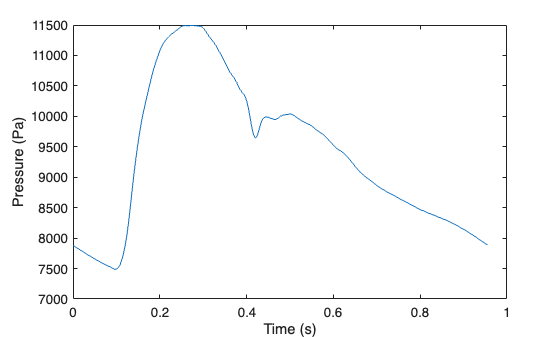

i = 1; % subject indice
subj = RADIAL_PHYSIO{i};
t = subj.ONE_CYCLE(:,1); % time (s)
P = subj.ONE_CYCLE(:,2); % pressure (Pa)
Q = subj.ONE_CYCLE(:,3); % flow (m^3/s)
A = subj.ONE_CYCLE(:,4); % area (m^2)
N = numel(RADIAL_PHYSIO);

figure;
plot(t, P); xlabel('Time (s)'); ylabel('Pressure (Pa)');

title('Radial Pressure Waveform, Example Subject');

## Distribution of Stiffness and Other Parameters

cfPWV_all = zeros(N,1);
for i = 1:N
    cfPWV_all(i) = COMPUTED_PHYSIO.PWV_PATH{i}.FootToFoot(2); % 2=cfPWV
end
figure; histogram(cfPWV_all,30)
xlabel('cfPWV (m/s)'); ylabel('Count');
title('Distribution of Carotid-Femoral Pulse Wave Velocity');


## Visualize Example Pulse Waveforms by Stiffness

% Sort by cfPWV
[~, idx_sort] = sort(cfPWV_all);

figure; hold on
for i = 1:600:N
    t = RADIAL_PHYSIO{idx_sort(i)}.ONE_CYCLE(:,1);
    P = RADIAL_PHYSIO{idx_sort(i)}.ONE_CYCLE(:,2);
    plot(t, P, 'DisplayName', sprintf('cfPWV=%.1f', cfPWV_all(idx_sort(i))))
end
xlabel('Time (s)'); ylabel('Pressure (Pa)');
legend; title('Radial Pulse Waveforms Across Stiffness Spectrum');
hold off


## Relation between Eel (stiffness) and Waveforms, Pulse height, cfPWV, etc.

Eel = COMPUTED_PHYSIO.PARAMETERS(:,8); % Column 8 = Elastic modulus (Eel) scaling
cfPWV = zeros(numel(Eel),1);
for i = 1:numel(Eel)
    cfPWV(i) = COMPUTED_PHYSIO.PWV_PATH{i}.FootToFoot(2); % 2 = cfPWV
end

% Sort by Eel (increasing stiffness)
[~, idx] = sort(Eel);

% Pick subjects evenly across stiffness range (e.g., 6 subjects)
Nshow = 6;
sel = round(linspace(1, length(idx), Nshow));
figure;
for i = 1:Nshow
    ind = idx(sel(i));
    t = RADIAL_PHYSIO{ind}.ONE_CYCLE(:,1);
    P = RADIAL_PHYSIO{ind}.ONE_CYCLE(:,2);
    subplot(Nshow,1,i)
    plot(t, P, 'k', 'LineWidth', 1.5)
    ylabel('Pressure (Pa)')
    title(sprintf('Eel=%.2f, cfPWV=%.2f m/s', Eel(ind), cfPWV(ind)))
    if i==Nshow
        xlabel('Time (s)')
    end
end
sgtitle('Waveform Shape Across Increasing Arterial Stiffness')

% Example: Pulse height vs. Eel
pulse_height = zeros(numel(Eel),1);
for i = 1:numel(Eel)
    P = RADIAL_PHYSIO{i}.ONE_CYCLE(:,2);
    pulse_height(i) = max(P) - min(P);
end

figure;
scatter(Eel, pulse_height, 20, cfPWV, 'filled')
xlabel('Elastic Modulus Scaling (Eel)')
ylabel('Pulse Height (Pa)')
colorbar; title('Pulse Height vs. Stiffness (colored by cfPWV)')



## Influence of Simulation Parameters on Stiffness and Morphology

% Extract stiffness parameters (columns 8 and 9 in .PARAMETERS)
Eel = COMPUTED_PHYSIO.PARAMETERS(:,8); % Elastic modulus scaling
Emusc = COMPUTED_PHYSIO.PARAMETERS(:,9);

% Scatter plot vs. cfPWV
figure;
scatter(Eel, cfPWV_all, 'b.');
xlabel('Elastic Modulus Scaling (Eel)'); ylabel('cfPWV (m/s)');
title('Effect of Elastic Modulus on Central Arterial Stiffness');

%% Principal Component Analysis (PCA) on Waveforms


## Feature Extraction for All Subjects

features = zeros(N, 6);  % [PulseHeight, UpstrokeTime, UpSlope, DownSlope, AUC, SystTime]
labels = zeros(N,1);     % cfPWV (central stiffness, label)

for i = 1:N
    subj = RADIAL_PHYSIO{i};
    P = subj.ONE_CYCLE(:,2);
    t = subj.ONE_CYCLE(:,1);

    % 1. Pulse Height
    pmin = min(P); pmax = max(P);
    features(i,1) = pmax - pmin;

    % 2. Upstroke time (from min to max)
    [~, imin] = min(P);
    [~, imax] = max(P);
    features(i,2) = t(imax) - t(imin);

    % 3. Upstroke Slope (max derivative in rising phase)
    dP = diff(P) ./ diff(t);
    if imax > imin
        features(i,3) = max(dP(imin:imax-1));
    else
        features(i,3) = NaN;
    end

    % 4. Downstroke Slope (min derivative after peak)
    if imax < length(dP)
        features(i,4) = min(dP(imax:end));
    else
        features(i,4) = NaN;
    end

    % 5. Area Under Curve (AUC)
    features(i,5) = trapz(t, P);

    % 6. Systolic time (time above mean)
    pmean = mean(P);
    syst_idx = find(P > pmean);
    features(i,6) = (length(syst_idx) / length(P)) * (t(end) - t(1));

    % 7. Label: cfPWV (central aortic stiffness)
    labels(i) = COMPUTED_PHYSIO.PWV_PATH{i}.FootToFoot(2); % 2=cfPWV
end

%check git


## Correlation Analysis Between All Features and Indices

% Suppose features matrix as before, add more if you want (e.g., HR, SV from parameters)
corr_mat = corr([features, labels]);
figure; imagesc(corr_mat);
colorbar;
set(gca, 'XTick', 1:7, 'XTickLabel', {'PulseHeight','UpTime','UpSlope','DownSlope','AUC','SystTime','cfPWV'});
set(gca, 'YTick', 1:7, 'YTickLabel', {'PulseHeight','UpTime','UpSlope','DownSlope','AUC','SystTime','cfPWV'});
title('Correlation Matrix of Features and cfPWV');

## Export data for using Python Machine Learning 

T = array2table([features, labels], ...
    'VariableNames', {'PulseHeight', 'UpstrokeTime', 'UpSlope', 'DownSlope', 'AUC', 'SystTime', 'cfPWV'});

writetable(T, 'radial_features_labels.csv');
disp('Feature table exported as radial_features_labels.csv');
